**Project 2: The Phosphorus Balance of Lake Washington**

**Given:**

General Information For Lake Washington in 1963:

- Lake surface area (SA) = $87\ldotp 6*{10}^6 \;m^2$

- Volume (V) = $2884*{10}^6 \;m^3$

- Mean depth (d) = $32\ldotp 9\;m$

Annual Water Influx:

- Sewage effluents ($Q_s$): $28*{10}^6 \;m^3 \;{\textrm{yr}}^{-1}$

- Tributaries and direct runoff ($Q_w$): $887*{10}^6 \;m^3 \;{\textrm{yr}}^{-1}$

- Total water influx ($Q_{\textrm{in}}$): $915*{10}^6 \;m^3 \;{\textrm{yr}}^{-1}$

Mean Phosphorus Concentration:

- $C_P$ = 57 ${\textrm{mg}\;m}^{-3}$

Annual Phosphorus Influx:

- Sewage effluents ($L_s$): $160*{10}^9 \;\mathrm{mg}\;{\mathrm{yr}}^{-1}$

- Streams ($L_w$): $40*{10}^9 \;\textrm{mg}\;{\textrm{yr}}^{-1}$

- Other sources ($L$): $3*{10}^9 \;\textrm{mg}\;{\textrm{yr}}^{-1}$

- Total phosphorus influx ($L_P$): $203*{10}^9 \;\textrm{mg}\;{\textrm{yr}}^{-1}$

**Required**

1.) Mathematical Questions:

        a.)  Write the rate form of the mass balance equation for P in Lake Washington and explain what each term represents.

        b.)  Find the solution of the equation derived in a.) for a constant influx rate of P and where the initial P concentration is $C_0$.

        c.)  What steady state (equilibrium) P concentration will be obtained if the influx rate is constant?

2.) Numerical Questions

        a.)  What was the average annual rate of increase in phosphorus concnetration from 1933 to 1963?

        b.)  What was the rate of P discharge through the outlet in 1963?  What was the rate of deposition in sediments in the same year?

        c.)  What steady state P concnetration would eventually prevail in Lake Washington if all sewage effluents were diverted?

        d.)  How long would it take for P concentration to reach 99% of steady state equilibrium if all sewage effluents were diverted simultaneously?

        e.)  If all sewage effluents are diverted gradually as indicated (25% in 1963, 45% in 1965, 99% in 1967), find the P concentration for each year from 1963 to 1960 from the mass balance equation.

        f.)  Plot predicted P concentration for both instantaneous and gradual diversion, versus time.  Include both predicted curves and actual data from Lake Washington for comparison.

        g.)  Develop a simple P vs $\mathrm{chl}-\alpha$ relationship, predict expected $\mathrm{chl}-\alpha$ concentrations and compare against the measured values.

**Sketch**

**Theory**

1.) Mathematical Questions:

        a.)  This involves using a simple zero-order mass balance to write an equation for P in Lake Washington using the given variables.

        b.)  This involves solving the following equation to calculate $C_E :C_E =\frac{L_P }{V}*\frac{V}{Q_{\mathrm{in}} *\left(A*S\right)}$

        c.)  Calculate equilibrium concentration using the following equation: $C_E =I*\theta$

2.) Numerical Questions:

        a.)  This requires averaging P concentration from 1933 to 1963 and then calculating a mass balance using the average concentration.

        b.)  Calculate volumetric loading to sediments ($I_{\mathrm{sed}}$) as $I_{\mathrm{sed}} =\frac{C_E -C_P }{\theta }$ (rearranged from $C_E =I*\theta$), multiply by volume to calculate total P loading to sediments.

        c.)  Calculate equilibrium P concentration as in part 1c.), except that total P loading $L_0 =L_P -L_S$

        d.)  Use a mass balance as in part a.), except that total P loading $L_0 =L_P -L_S$.  Then, solve for the number of years for $C_{\mathrm{P1}} =1\ldotp 01*C_E$

        e.)  This requires 3 mass balances as in part d.) with three different values of $L_P$ representing the 25%, 45%, and 99% reductions in P loading through the 1960s.

        f.)  This is a line plot of measured vs calculated P concentrations from part e.)

        g.)  $\mathrm{chl}-\alpha$ will be calculated using the following equation from the lecture on 2/1/23: $\mathrm{chl}-\alpha =1886*{\left\lbrack \frac{L_P }{Q_{\mathrm{in}} +\left(S*A\right)}\right\rbrack }^{1\ldotp 449}$

**Assumptions**

1.) Mathematical Questions:

        a.)  

- Assume no decay of P over time

- Assume P concentration is spatially uniform

- Outflow due to sedimentation ($Q_{\mathrm{out}}$) is proportional to $C_P$ and is equal to ($Q_{\mathrm{in}}$).  Basically assume that the lake water level does not experience a net increase or decrease over time.

        b.)  

- Assumes a constant P influx rate

- Initial P concentration $C_0$ = $C_P$ in this case (same variable)

- Assume P settling velocity = $S=28\;m/\mathrm{yr}$ (lecture notes)

        c.)

- Assume equilibrium concentration $C_E =I*\theta$

2.) Numerical Questions:

        a.)

- Assume all variables except for P concentration (including P loading) remained constant from 1933 to 1963

- Assume $Q_{\mathrm{out}} =Q_{\mathrm{in}}$ 

        b.)

- Assume no losses to evaporation

- Assume that P is in steady state

- Assume $Q_{\mathrm{out}} =Q_{\mathrm{in}}$

- Assume concentration of P to sediments = $C_E -C_P$

        c.)

- Assume $L_s =0\;\mathrm{mg}/\mathrm{yr}\;$

        d.)

- Assume final P concentration is 99% of the steady-state P concentration

        e.)

- 25% P loading reduction from 1963-64, 45% P loading reduction from 1965-1966, 99% P loading reduction from 1967-69.

- 
$$C_{\mathrm{P1963}} =C_P =57\;\mathrm{mg}/m^3$$


- P residence time stays constant

        f.)  

- No new assumptions

        g.)

- Assume $L_P$ changes according to reductions in $L_s$ from 1963 to 1969 as in part e.)

**Solution**

First, all given information for both questions was input into MATLAB and saved as variables:

SA = 87.6e6; %surface area
V = 2884e6; %lake volume
d = 32.9; %lake depth
Qs = 28e6; %sewage water influx
Qw = 887e6; %streams and tributaries water influx
Qin = 915e6; %total water influx
CP = 57; %mean P concentration
Ls = 160e9; %P influx from sewage
Lw = 40e9; %P influx from streams
L = 3e9; %P influx from other sources
LP = 203e9; %total P influx

1.) Mathematical Questions:

        a.)

  
$$\frac{\mathrm{dC}}{\mathrm{dt}}=\frac{L_P }{V}-C_P *\frac{Q_{\mathrm{out}} }{V}$$



$$\frac{\mathrm{dC}}{\mathrm{dt}}=I-C_P *\frac{1}{\theta }$$


- $\frac{\mathrm{dC}}{\mathrm{dt}}$ = Change in P concentration over time

- $L_P$ = Total P influx

- ${\;L}_s +L_w$ = P influx from sewage effluent and streams, respectively (not used).

- $V$= Lake volume

- $C_P$ = Mean P concentration in the lake

- $Q_{\mathrm{out}}$ = Total water outflow/losses

- $I$= Net P load/volume

- $\theta$ = P residence time

        b.)

First, solve for $I$ and $1/\theta$.


$$I=\frac{L_P }{V}$$


I = LP/V

I = 70.3883


$$I=70\ldotp 4\;\mathrm{mg}/m^3 \;\mathrm{yr}$$



$$1/\theta =\frac{Q_{\mathrm{out}} +A*S}{V}$$


A = 87.6e6; %m^2 (surface area)
S = 24; %m/s (settling velocity)
O = (Qin+(A*S))/V %used O to represent 1/theta in MATLAB code

O = 1.0463


$$1/\theta =1\ldotp 05\;{\mathrm{yr}}^{-1}$$


Solve for $\frac{\mathrm{dC}}{\mathrm{dt}}$:


$$\frac{\mathrm{dC}}{\mathrm{dt}}=I-C_P *\frac{1}{\theta }$$


Ct = I-CP*O %Ct used to represent concentration change per year in MATLAB code

Ct = 10.7518


$$\frac{\mathrm{dC}}{\mathrm{dt}}=10\ldotp 75\;\mathrm{mg}/m^3 \;\mathrm{yr}$$


        c.)


$$C_E =I*\theta$$


CE = I*(V/(Qin+(A*S))) %CE represents equilibrium concentration

CE = 67.2765


$$C_E =67\ldotp 3\;\mathrm{mg}/m^3$$


2.) Numerical Questions:

        a.)

Calculate average P concentration from 1933 to 1963:

CP1933 = 6; %mg/m^3 in 1933
CPaverage = (CP1933+CP)/2

CPaverage = 31.5000


$$C_{P\;\left(\mathrm{average}\right)} =31\ldotp 5\;\mathrm{mg}/m^3$$


Solve for $\frac{\mathrm{dC}}{\mathrm{dt}}\;\left(1933-1963\right)$:


$$\frac{\mathrm{dC}}{\mathrm{dt}}\;\left(1933\right)=I-C_{P\;\left(\mathrm{average}\right)} *\frac{1}{\theta }$$


Ct1933 = I-CPaverage*O %Ct used to represent concentration change per year in MATLAB code

Ct1933 = 37.4313


$$\frac{\mathrm{dC}}{\mathrm{dt}}\;\left(1933-1963\right)=37\ldotp 4\;\mathrm{mg}/m^3 \;\mathrm{yr}$$


        b.)

Calculate volumetric discharge of P via sedimentation: $I_{\mathrm{sed}} =\frac{C_E -C_P }{\theta }$ 

Ised = (CE-CP)/(1/O)

Ised = 10.7518

$I_{\mathrm{sed}} =10\ldotp 8\;\mathrm{mg}/m^3 \;\mathrm{yr}$, multiply by volume to calculate total discharge to sediments: $L_{\mathrm{sed}} =I_{\mathrm{sed}} *V$

Lsed=Ised*V

Lsed = 3.1008e+10


$$L_{\mathrm{sed}} =3\ldotp 10*{10}^{10} \;\mathrm{mg}/\mathrm{yr}$$


Calculate discharge of P through the outlet: $L_{\mathrm{out}} =L_P -L_{\mathrm{sed}}$

Lout = LP-Lsed

Lout = 1.7199e+11


$$L_{\mathrm{out}} =1\ldotp 72*{10}^{11} \;\mathrm{mg}/\mathrm{yr}$$


        c.)

Calculate volumetric P loading assuming that $L_0 =L_P -L_s$


$$I_0 =\frac{L_0 }{V}$$


I0 = (LP-Ls)/V

I0 = 14.9098


$$I_0 =14\ldotp 9\;\mathrm{mg}/m^3 \;\mathrm{yr}$$


Solve for $C_{\mathrm{E0}}$ substituting $I_0$ for $I$: $C_E =I_0 *\theta$

CE0 = I0*(1/O) %CE0 = equilibrium concentration with no sewage P input

CE0 = 14.2507


$$C_{\mathrm{E0}} =14\ldotp 3\;\mathrm{mg}/m^3$$


        d.)

Solve for mass balance using $I_0$ from part c.): $\frac{\mathrm{dC}}{\mathrm{dt}}=I_0 -C_P *\frac{1}{\theta }$

Ct1 = I0-(CP*O)

Ct1 = -44.7267


$$\frac{\mathrm{dC}}{\mathrm{dt}}=-44\ldotp 7\;\mathrm{mg}/m^3 \;\mathrm{yr}$$


Find 99% of $C_E =C_{\mathrm{P1}} =1\ldotp 01*C_{\mathrm{E0}}$

CP1 = CE0*1.01

CP1 = 14.3932


$$C_{\mathrm{P1}} =14\ldotp 4\;\mathrm{mg}/m^3$$


Solve for t in the following equation to find number of years to go from $C_P$ to $C_{\mathrm{P1}}$:


$$C_{\mathrm{P1}}$$

$$=C_P +\frac{\mathrm{dC}}{\mathrm{dt}}*t\longrightarrow t=\frac{C_{\mathrm{P1}} -C_P }{\frac{\mathrm{dC}}{\mathrm{dt}}}$$


t=(CP1-CP)/Ct1

t = 0.9526


$$t=0\ldotp 95\;\mathrm{years}$$


        e.)

**1963: **$C_{\mathrm{P1963}} =C_P =57\ldotp 0\;\mathrm{mg}/m^3$

Calculate concentration for each year as $\Delta C=I-C_P *\frac{1}{\theta }\longrightarrow C_{\mathrm{xyear}} =C_{\mathrm{previous}\;\mathrm{yr}} +\Delta C$

**1964: **

calculate $I_{63\mathrm{to64}}$ as $I_{63\mathrm{to64}} =\frac{L_P -0\ldotp 25*L_S }{V}$, then calculate$\Delta C=I_{63\mathrm{to64}} -C_P *\frac{1}{\theta }$ 

I63to64=(LP-(0.25*Ls))/V; %25 percent reduction in P load from sewage
Ct63to64=I63to64-(CP*O); %change in concentration from 1963 to 1964
C1964=CP+Ct63to64 %P concentration for 1964

C1964 = 53.8822


$$C_{P1964} =53\ldotp 9\;\mathrm{mg}/m^3$$


**1965:**

calculate $I_{64\mathrm{to65}}$ as $I_{64\mathrm{to65}} =\frac{L_P -0\ldotp 45*L_S }{V}$, then calculate$\Delta C=I_{64\mathrm{to65}} -C_{\mathrm{P1964}} *\frac{1}{\theta }$ 

I64to65=(LP-(0.45*Ls))/V; %45 percent reduction in P load from sewage
Ct64to65=I64to65-(C1964*O); %change in concentration from 1964 to 1965
C1965=C1964+Ct64to65 %P concentration for 1965

C1965 = 42.9307


$$C_{P1965} =42\ldotp 9\;\mathrm{mg}/m^3$$


**1966:**

calculate$\Delta C=I_{64\mathrm{to65}} -C_{\mathrm{P1965}} *\frac{1}{\theta }$

Ct65to66=I64to65-(C1965*O); %change in concentration from 1965 to 1966
C1966=C1965+Ct64to65 %P concentration for 1966

C1966 = 31.9792


$$C_{P1966} =32\ldotp 0\;\mathrm{mg}/m^3$$


**1967:**

calculate $I_{66\mathrm{to67}}$ as $I_{66\mathrm{to67}} =\frac{L_P -0\ldotp 99*L_S }{V}$, then calculate$\Delta C=I_{66\mathrm{to67}} -C_{\mathrm{P1966}} *\frac{1}{\theta }$ 

I66to67=(LP-(0.99*Ls))/V; %99 percent reduction in P load from sewage
Ct66to67=I66to67-(C1966*O); %change in concentration from 1966 to 1967
C1967=C1966+Ct66to67 %P concentration for 1967

C1967 = 13.9854


$$C_{P1967} =14\ldotp 0\;\mathrm{mg}/m^3$$


**1968:**

calculate$\Delta C=I_{66\mathrm{to67}} -C_{\mathrm{P1967}} *\frac{1}{\theta }$

Ct67to68=I66to67-(C1967*O); %change in concentration from 1967 to 1968
C1968=C1967+Ct67to68 %P concentration for 1968

C1968 = 14.8177


$$C_{P1968} =14\ldotp 8\;\mathrm{mg}/m^3$$


**1969:**

calculate$\Delta C=I_{66\mathrm{to67}} -C_{\mathrm{P1968}} *\frac{1}{\theta }$

Ct68to69=I66to67-(C1968*O); %change in concentration from 1968 to 1969
C1969=C1968+Ct67to68 %P concentration for 1969

C1969 = 15.6500


$$C_{P1968} =15\ldotp 7\;\mathrm{mg}/m^3$$


        f.)

Input actual P concentrations measured from Lake Washington from 1963-1969 into MATLAB as variables representing year and concentration ($\mathrm{mg}/m^3$)

yr = [1963, 1964, 1965, 1966, 1967, 1968, 1969]; %year input
Pconc = [57, 56, 51, 34, 31, 11, 16,]; %measured P concentrations (mg/m^3)
Pcalc = [CP, C1964, C1965, C1966, C1967, C1968, C1969]; %calculated P concentrations (mg/m^3)

Graph P concentration vs time:

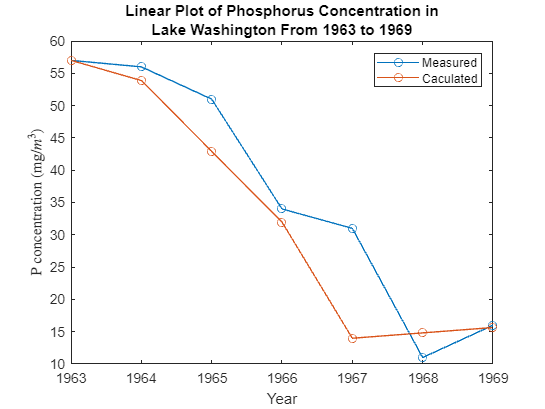

figure
plot(yr,Pconc,'o-')
hold on
plot(yr,Pcalc, 'o-')
hold off
title(["Linear Plot of Phosphorus Concentration in", "Lake Washington From 1963 to 1969"])
ylabel("P concentration (mg/$m^{3}$)", 'Interpreter', 'latex')
xlabel("Year")
legend("Measured", "Caculated")

        g.)

**1963:** $\mathrm{chl}-\alpha =1886*{\left\lbrack \frac{L_P }{Q_{\mathrm{in}} +\left(S*A\right)}\right\rbrack }^{1\ldotp 449}$

c63 = 1886*((LP/(Qin+(S*A)))^1.449)

c63 = 8.3968e+05

c64 = 1886*((LP-(0.25*Ls)/(Qin+(S*A)))^1.449)

c64 = 4.5720e+19

**Discussion**

1.) Mathematical Questions:

        a.)

        b.)

        c.)

2.) Numerical Questions:

        a.)

        b.)

        c.)

        d.)

        e.)

        f.)

        g.)